%% read and reshape data
clear all
close all
[traindata, trainlabels] = mnist_parse('train-images-idx3-ubyte', 'train-labels-idx1-ubyte');

Magic Number - Images: 2051
Magic Number - Labels: 2049
Total number of images: 60000
Dimensions of each digit: 28 x 28


A = double(reshape(traindata, size(traindata,1)*size(traindata,2), []).');
%trainlabels = double(trainlabels);
[testdata, testlabels] = mnist_parse('t10k-images-idx3-ubyte', 't10k-labels-idx1-ubyte');

Magic Number - Images: 2051
Magic Number - Labels: 2049
Total number of images: 10000
Dimensions of each digit: 28 x 28


testdata = double(reshape(testdata, size(testdata,1)*size(testdata,2), []).');
%testlabels = double(testlabels);

%[images, labels] = mnist_parse('train-images-idx3-ubyte', 'train-labels-idx1-ubyte');
%[images, labels] = mnist_parse('t10k-images-idx3-ubyte', 't10k-labels-idx1-ubyte');
%A = images;
%B = labels;
%reshape trainlabels
n = length(trainlabels);
B = zeros(n,10);
for  i = 1:n
    k = trainlabels(i);
    if k == 0
        k = 10;
    end
    
    B(i,k) = 1; 
end
A = A';
B =B';


## comparison of methods

%X1=B*pinv(A);  
%X2=A\B; 



%[X3,stats]=lasso(A,trainlabels); 

%[X4,stats]=lasso(A,trainlabels,'Alpha',0.8); 

%X5 =robustfit(A,trainlabels); %gives a vector answer

%X6 =ridge(trainlabels,A,0.5,0);%gives a vector

%cross validation 
%divide data into to k = 6 parts 
p = randperm(60000);
A1 = A(:,p(1:10000));
A2 = A(:,p(10001:20000));
A3 = A(:,p(20001:30000));
A4 = A(:,p(30001:40000));
A5 = A(:,p(40001:50000));
A6 = A(:,p(50001:60000));

B1 = B(:,p(1:10000));
B2 = B(:,p(10001:20000));
B3 = B(:,p(20001:30000));
B4 = B(:,p(30001:40000));
B5 = B(:,p(40001:50000));
B6 = B(:,p(50001:60000));


%pseudo inverse crossvalidation
X11=B1*pinv(A1);
X12=B2*pinv(A2);
X13=B3*pinv(A3);
X14=B4*pinv(A4);
X15=B5*pinv(A5);
X16=B6*pinv(A6);
Xpinv = (X11 + X12 + X13 + X14 + X15 + X16)./6;

%/ cross validation
X21 = B1/A1;

X22 = B2/A2;

X23 = B3/A3;

X24 = B4/A4;

X25 = B5/A5;

X26 = B6/A6;

Xback = (X21 + X22 + X23 + X24 + X25 + X26)./6;
%subplot(2,1,1), pcolor(Xback), subplot(2,1,2), pcolor(X21)

%separate vector labels
b1 = trainlabels(p(1:10000));
b2 = trainlabels(p(10001:20000));
b3 = trainlabels(p(20001:30000));
b4 = trainlabels(p(30001:40000));
b5 = trainlabels(p(40001:50000));
b6 = trainlabels(p(50001:60000));

%crossvalidated lasso lambda = 0.1 

for i = 1:10
    [X31,stats]=lasso(A',B(i,:), 'Lambda', 0.1,'CV',6);
    Xlass1(i,:) = X31;
end

%crossvalidated lasso lamba = 0.5 and 0.9
for i = 1:10
    [X32,stats]=lasso(A',B(i,:), 'Lambda', 0.5,'CV',6);
    Xlass2(i,:) = X32;
end

for i = 1:10
    [X33,stats]=lasso(A',B(i,:), 'Lambda', 0.9,'CV',6);
    Xlass3(i,:) = X33;
end

% other lasso crossvalidation

for i = 1:10
    [X41,stats]=lasso(A',B(i,:), 'Lambda', 0.1,'Alpha',0.8,'CV',6);
    Xlass1a(i,:) = X41;
end

% robust fit crossvalidation
for i = 1:1
    X51 = robustfit(A1',B1(i,:));
    X52 = robustfit(A2',B2(i,:));
    X53 = robustfit(A3',B3(i,:));
    X54 = robustfit(A4',B4(i,:));
    X55 = robustfit(A5',B5(i,:));
    X56 = robustfit(A6',B6(i,:));
    Xrob1(i,:) = X51;
    Xrob2(i,:) = X52;
    Xrob3(i,:) = X53;
    Xrob4(i,:) = X54;
    Xrob5(i,:) = X55;
    Xrob6(i,:) = X56;
    
end

 Xrob1n = Xrob1(:, 2:end);
 Xrob2n = Xrob2(:, 2:end);
 Xrob3n = Xrob3(:, 2:end);
 Xrob4n = Xrob4(:, 2:end);
 Xrob5n = Xrob5(:, 2:end);
 Xrob6n = Xrob6(:, 2:end);

%create final robust sol
Xrob = (Xrob1n + Xrob2n + Xrob3n + Xrob4n + Xrob5n + Xrob6n)/6;

%ridge
for i = 1:10
    X61 = ridge(B1(i,:)', A1',0.5,1);
    X62 = ridge(B2(i,:)', A2', 0.5,1);
    X63 = ridge(B3(i,:)', A3',0.5,1);
    X64 = ridge(B4(i,:)', A4',0.5,1);
    X65 = ridge(B5(i,:)', A5', 0.5,1);
    X66 = ridge(B6(i,:)', A6',0.5,1);
    Xrig1(i,:) = X61;
    Xrig2(i,:) = X62;
    Xrig3(i,:) = X63;
    Xrig4(i,:) = X64;
    Xrig5(i,:) = X65;
    Xrig6(i,:) = X66;
    
end


%final ridge sol
Xrig = (Xrig1 + Xrig2 + Xrig3 + Xrig4 + Xrig5 + Xrig6)/6;


subplot(2,2,1)
vis1 = reshape(Xpinv(1,:),28,28);
pcolor(vis1)

subplot(2,2,2)
vis2 = reshape(Xpinv(2,:),28,28);
pcolor(vis2)

subplot(2,2,3)
vis3 = reshape(Xpinv(3,:),28,28);
pcolor(vis3)

subplot(2,2,4)
vis4 = reshape(Xpinv(8,:),28,28);
pcolor(vis4)

% vis1 = reshape(Xback(2,:),28,28);
% pcolor(vis1)
% 
% vis2 = reshape(Xlass1(2,:),28,28);
% pcolor(vis2)
% 
% vis3 = reshape(Xlass2(2,:),28,28);
% pcolor(vis3)
% 
% vis4 = reshape(Xlass3(2,:),28,28);
% pcolor(vis4)


figure(1)
pcolor(Xpinv(:,R))

%threshold
Xpinvthresh = (Xpinv>.01).*Xpinv;
Xbackthresh = (Xback>.01).*Xback;
Xlass1thresh = (Xlass1>.01).*Xlass1;
Xlass2thresh = (Xlass2>.01).*Xlass2;
Xlass3thresh = (Xlass3>.01).*Xlass3;
Xlass1athresh = (Xlass1a>.01).*Xlass1a;
Xrobthresh = (Xrob>.01).*Xrob;
Xrigthresh = (Xrig>.01).*Xrig;

%choose test solver on thresh X
Atest = testdata';
Bpinvth = Xpinvthresh*Atest;
Bbackth = Xbackthresh*Atest;
Blass1th = Xlass1thresh * Atest;
Blass2th = Xlass2thresh*Atest;
Blass3th = Xlass3thresh*Atest;
Blass1ath = Xlass1athresh*Atest;
Brigth = Xrigthresh*Atest;
Brobth = Xrobthresh*Atest;

%how many did each get correct in extrapolated data?
[Mp,Ip] = max(Bpinv);
[Mback,Iback] = max(Bback);
[Mlass1,Ilass1] = max(Blass1);
[Mlass2,Ilass2] = max(Blass2);
[Mlass3,Ilass3] = max(Blass3);
[Mlass1a,Ilass1a] = max(Blass1a);
[Mrob,Irob] = max(Brob);
[Mrig,Irig] = max(Brig);
testlabels2 = testlabels;
for i = 1:length(testlabels)
    if testlabels(i) == 0
        testlabels2(i) =10;
    end
end
diff1 = Ip' - testlabels2;
diff2 = Iback' - testlabels2;
diff3 = Ilass1' - testlabels2;
diff4 = Ilass2' - testlabels2;
diff5 = Ilass3' - testlabels2;
diff6 = Ilass1a' - testlabels2;
diff7 = Irob' - testlabels2;
diff8 = Irig' - testlabels2;

numCor(1) = size(find(~diff1),1);
numCor(2) = size(find(~diff2),1);
numCor(3) = size(find(~diff3),1);
numCor(4) = size(find(~diff4),1);
numCor(5) = size(find(~diff5),1);
numCor(6) = size(find(~diff6),1);
numCor(7) = size(find(~diff7),1);
numCor(8) = size(find(~diff8),1);



%checking error
errPinvth = norm(Btest - Bpinvth);
errbackth = norm(Btest - Bbackth);
errlass1th = norm(Btest - Blass1th);
errlass2th = norm(Btest - Blass2th);
errlass3th = norm(Btest - Blass3th);
errlass1ath = norm(Btest - Blass1ath);
errRobth = norm(Btest - Brobth);
errRigth = norm(Btest - Brigth);
errorth = [errPinvth; errbackth; errlass1th; errlass2th; errlass3th;errlass1ath;errRobth;errRigth];
table(errorth)

%choose best solver by checking accuracy on test data
Atest = testdata';
Bpinv = Xpinv*Atest;
Bback = Xback*Atest;
Blass1 = Xlass1 * Atest;
Blass2 = Xlass2*Atest;
Blass3 = Xlass3*Atest;
Blass1a = Xlass1a*Atest;
Brig = Xrig*Atest;
Brob = Xrob*Atest;

%how many did each get correct in thresh versions
[Mpth,Ipth] = max(Bpinvth);
[Mbackth,Ibackth] = max(Bbackth);
[Mlass1th,Ilass1th] = max(Blass1th);
[Mlass2th,Ilass2th] = max(Blass2th);
[Mlass3th,Ilass3th] = max(Blass3th);
[Mlass1ath,Ilass1ath] = max(Blass1ath);
[Mrobth,Irobth] = max(Brobth);
[Mrigth,Irigth] = max(Brigth);

diff1th = Ipth' - testlabels2;
diff2th = Ibackth' - testlabels2;
diff3th = Ilass1th' - testlabels2;
diff4th = Ilass2th' - testlabels2;
diff5th = Ilass3th' - testlabels2;
diff6th = Ilass1ath' - testlabels2;
diff7th = Irobth' - testlabels2;
diff8th = Irigth' - testlabels2;

numCorth(1) = size(find(~diff1th),1);
numCorth(2) = size(find(~diff2th),1);
numCorth(3) = size(find(~diff3th),1);
numCorth(4) = size(find(~diff4th),1);
numCorth(5) = size(find(~diff5th),1);
numCorth(6) = size(find(~diff6th),1);
numCorth(7) = size(find(~diff7th),1);
numCorth(8) = size(find(~diff8th),1);

%find most sparse solver
k1 = find(Xpinvthresh);
k2 = find(Xbackthresh);
k3 = find(Xlass1thresh);
k4 = find(Xlass2thresh);
k5 = find(Xlass3thresh);
k6 = find(Xlass1athresh);
k7 = find(Xrobthresh);
k8 = find(Xrigthresh);



%reshape test labels
nn = length(testlabels);
Btest = zeros(nn,10);
for  i = 1:nn
    k = testlabels(i);
    if k == 0
        k = 10;
    end
    
    Btest(i,k) = 1; 
end

Btest =Btest';

%checking error
errPinv = norm(Btest - Bpinv);
errback = norm(Btest - Bback);
errlass1 = norm(Btest - Blass1);
errlass2 = norm(Btest - Blass2);
errlass3 = norm(Btest - Blass3);
errlass1a = norm(Btest - Blass1a);
errRob = norm(Btest - Brob);
errRig = norm(Btest - Brig);
error = [errPinv; errback; errlass1; errlass2; errlass3;errlass1a;errRob;errRig];
table(error)

%rank pixels for whole space: 
%which pixels show up for most digits
for i = 1:784
    most(i) = norm(Xlass1a(:,i));
end

R = find(most);
rank = most(R)

rank = 	1.0e+-3 *

    0.0601    0.1374    0.0208    0.0823    0.0393    0.0253    0.0844    0.0846    0.1157    0.1733    0.1306    0.0338    0.0498    0.0416    0.1974    0.2431    0.1263    0.1180    0.1416    0.0652    0.0713    0.0848    0.1653    0.0184    0.3729    0.2096    0.0136    0.3303    0.0517    0.0228    0.0631    0.3162    0.2041    0.1951    0.0770    0.0205    0.1390    0.0695    0.1187    0.0447    0.3381    0.0236    0.2503    0.1848    0.0294    0.0473    0.0171    0.6609    0.0121    0.0289


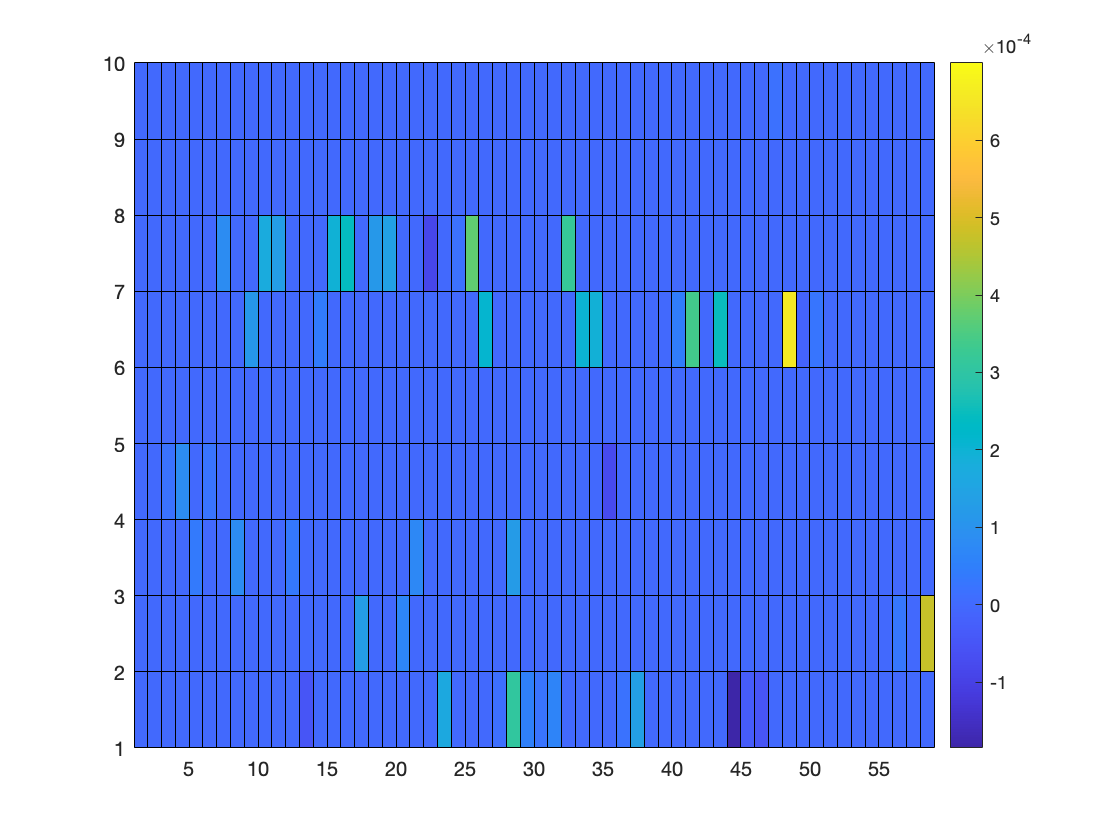

figure(4)
pcolor(Xlass1a(:,R))

colorbar

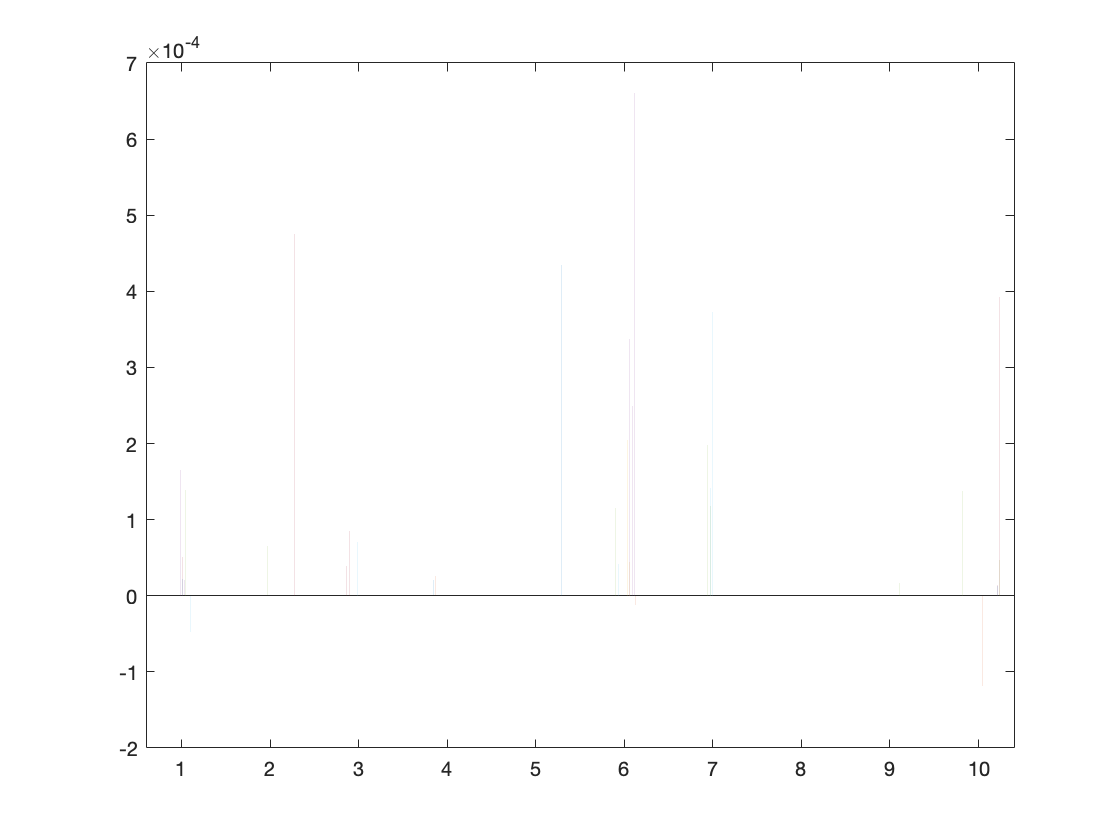

bar(Xlass1a)

%identify correctly labeled images in lass1a
y = find(~diff6);
A_LC = A(:,y);

%analysis with each digit individually

labels_1 = find(trainlabels == 1);
labels_2 = find(trainlabels == 2);
labels_3 = find(trainlabels == 3);
labels_4 = find(trainlabels == 4);
labels_5 = find(trainlabels == 5);
labels_6 = find(trainlabels == 6);
labels_7 = find(trainlabels == 7);
labels_8 = find(trainlabels == 8);
labels_9 = find(trainlabels == 9);
labels_0 = find(~trainlabels);

%run analysis on 1's
%A_1 = A(:,labels_1);
nn = size(A,2);
B_1 = zeros(nn,1);
B_1(labels_1) = 1;
%B_1(1,:) = 1;
[X_1,stats]=lasso(A',B_1,'Lambda', 0.1,'Alpha',.8,'CV',6);

% for i = 1:10 %giving zero matrix
%     [Xlass_1,stats]=lasso(A_1',B_1(i,:), 'Lambda', 0.1,'Alpha',.8,'CV',6);
%     X_1(i,:) = Xlass_1;
% end
%X_1 = B_1/A_1;

bar(X_1)

title('Digit 1')
pcolor(reshape(X_1,28,28))

xlim([1.0 28.0])
ylim([1.0 28.0])
colorbar
title('Digit 1')


%run analysis on 2
B_2 = zeros(nn,1);
B_2(labels_2) = 1;
[X_2,stats]=lasso(A',B_2,'Lambda', 0.1,'Alpha',.8,'CV',6);


%run analysis on 3
B_3 = zeros(nn,1);
B_3(labels_3) = 1;
[X_3,stats]=lasso(A',B_3,'Lambda', 0.1,'Alpha',.8,'CV',6);
bar(X_3)
title('Digit 3')
pcolor(reshape(X_3,28,28))
xlim([1.0 28.0])
ylim([1.0 28.0])
colorbar
title('Digit 3')

%run analysis on 4
B_4 = zeros(nn,1);
B_4(labels_2) = 1;
[X_4,stats]=lasso(A',B_4,'Lambda', 0.1,'Alpha',.8,'CV',6);
bar(X_4)
title('Digit 4')

pcolor(reshape(X_4,28,28))
xlim([1.0 28.0])
ylim([1.0 28.0])
colorbar
title('Digit 4')

%run analysis on 5
B_5 = zeros(nn,1);
B_5(labels_5) = 1;
[X_5,stats]=lasso(A',B_5,'Lambda', 0.1,'Alpha',.8,'CV',6);
bar(X_5)
title('Digit 5')

pcolor(reshape(X_5,28,28))
xlim([1.0 28.0])
ylim([1.0 28.0])
colorbar
title('Digit 5')

%run analysis on 6
B_6 = zeros(nn,1);
B_6(labels_6) = 1;
[X_6,stats]=lasso(A',B_6,'Lambda', 0.1,'Alpha',.8,'CV',6);
bar(X_6)
title('Digit 6')

pcolor(reshape(X_6,28,28))
xlim([1.0 28.0])
ylim([1.0 28.0])
colorbar
title('Digit 6')

%run analysis on 7
B_7 = zeros(nn,1);
B_7(labels_7) = 1;
[X_7,stats]=lasso(A',B_7,'Lambda', 0.1,'Alpha',.8,'CV',6);
bar(X_7)
title('Digit 7')

pcolor(reshape(X_7,28,28))
xlim([1.0 28.0])
ylim([1.0 28.0])
colorbar
title('Digit 7')

%run analysis on 8
B_8 = zeros(nn,1);
B_8(labels_8) = 1;
[X_8,stats]=lasso(A',B_8,'Lambda', 0.1,'Alpha',.8,'CV',6);
bar(X_8)
title('Digit 8')

pcolor(reshape(X_8,28,28))
xlim([1.0 28.0])
ylim([1.0 28.0])
colorbar
title('Digit 8')


%run analysis on 9
B_9 = zeros(nn,1);
B_9(labels_9) = 1;
[X_9,stats]=lasso(A',B_9,'Lambda', 0.1,'Alpha',.8,'CV',6);
bar(X_9)
title('Digit 9')

pcolor(reshape(X_9,28,28))
xlim([1.0 28.0])
ylim([1.0 28.0])
colorbar
title('Digit 9')

%run analysis on 0
B_0 = zeros(nn,1);
B_0(labels_0) = 1;
[X_0,stats]=lasso(A',B_0,'Lambda', 0.1,'Alpha',.8,'CV',6);
bar(X_0)
title('Digit 0')

pcolor(reshape(X_0,28,28))
xlim([1.0 28.0])
ylim([1.0 28.0])
colorbar
title('Digit 0')

figure(2)
subplot(5,4,1)
bar(X_1)
title('Digit 1')

subplot(5,4,2)
pcolor(reshape(X_1,28,28))
xlim([1.0 28.0])
ylim([1.0 28.0])
colorbar
title('Digit 1')

subplot(5,4,3)
bar(X_2)
title('Digit 2')

subplot(5,4,4)
pcolor(reshape(X_2,28,28))
xlim([1.0 28.0])
ylim([1.0 28.0])
colorbar
title('Digit 2')

subplot(5,4,5)
bar(X_3)
title('Digit 3')
subplot(5,4,6)
pcolor(reshape(X_3,28,28))
xlim([1.0 28.0])
ylim([1.0 28.0])
colorbar
title('Digit 3')

subplot(5,4,7)
bar(X_4)
title('Digit 4')
subplot(5,4,8)
pcolor(reshape(X_4,28,28))
xlim([1.0 28.0])
ylim([1.0 28.0])
colorbar
title('Digit 4')

subplot(5,4,9)
bar(X_5)
title('Digit 5')
subplot(5,4,10)
pcolor(reshape(X_5,28,28))
xlim([1.0 28.0])
ylim([1.0 28.0])
colorbar
title('Digit 5')

subplot(5,4,11)
bar(X_6)
title('Digit 6')
subplot(5,4,12)
pcolor(reshape(X_6,28,28))
xlim([1.0 28.0])
ylim([1.0 28.0])
colorbar
title('Digit 6')

subplot(5,4,13)
bar(X_7)
title('Digit 7')
subplot(5,4,14)
pcolor(reshape(X_7,28,28))
xlim([1.0 28.0])
ylim([1.0 28.0])
colorbar
title('Digit 7')

subplot(5,4,15)
bar(X_8)
title('Digit 8')
subplot(5,4,16)
pcolor(reshape(X_8,28,28))
xlim([1.0 28.0])
ylim([1.0 28.0])
colorbar
title('Digit 8')

subplot(5,4,17)
bar(X_9)
title('Digit 9')
subplot(5,4,18)
pcolor(reshape(X_9,28,28))
xlim([1.0 28.0])
ylim([1.0 28.0])
colorbar
title('Digit 9')

subplot(5,4,19)
bar(X_0)
title('Digit 0')
subplot(5,4,20)
pcolor(reshape(X_0,28,28))
xlim([1.0 28.0])
ylim([1.0 28.0])
colorbar
title('Digit 0')

method = {'pinv'; 'forward'; 'lasso1';'lasso2';'lasso3'; 'lasso1a'; 'robustfit'; 'ridge'};
T = table(numCor', 'RowNames',method, 'VariableNames',{'NumCorrect'})


figure(3)

subplot(5,2,1)
pcolor(reshape(X_1,28,28))
xlim([1.0 28.0])
ylim([1.0 28.0])
colorbar
title('Digit 1')

subplot(5,2,2)
pcolor(reshape(X_2,28,28))
xlim([1.0 28.0])
ylim([1.0 28.0])
colorbar
title('Digit 2')

subplot(5,2,3)
pcolor(reshape(X_3,28,28))
xlim([1.0 28.0])
ylim([1.0 28.0])
colorbar
title('Digit 3')

subplot(5,2,4)
pcolor(reshape(X_4,28,28))
xlim([1.0 28.0])
ylim([1.0 28.0])
colorbar
title('Digit 4')

subplot(5,2,5)
pcolor(reshape(X_5,28,28))
xlim([1.0 28.0])
ylim([1.0 28.0])
colorbar
title('Digit 5')

subplot(5,2,6)
pcolor(reshape(X_6,28,28))
xlim([1.0 28.0])
ylim([1.0 28.0])
colorbar
title('Digit 6')

subplot(5,2,7)
pcolor(reshape(X_7,28,28))
xlim([1.0 28.0])
ylim([1.0 28.0])
colorbar
title('Digit 7')

subplot(5,2,8)
pcolor(reshape(X_8,28,28))
xlim([1.0 28.0])
ylim([1.0 28.0])
colorbar
title('Digit 8')

subplot(5,2,9)
pcolor(reshape(X_9,28,28))
xlim([1.0 28.0])
ylim([1.0 28.0])
colorbar
title('Digit 9')

subplot(5,2,10)
pcolor(reshape(X_0,28,28))
xlim([1.0 28.0])
ylim([1.0 28.0])
colorbar
title('Digit 0')